## Part 1_2

.در ابتدا سیگنال های داده شده را لود کرده و آن ها رسم میکنیم

.فرکانس نمونه برداری با توجه به داده های فایل برابر 199.64 است که آن را گرد میکنیم و برابر 200 هرتز میگیریم

.برای رسم آن ها ستون اول از فایل ها را انتخاب میکنیم و با توجه به آنکه ماتریس ما عمودی است، آن را با دستور زیر سطر و ستونش را جابجا میکنیم

transpose : interchange the row and column

.حال فوریه آن ها را نیز میگیریم

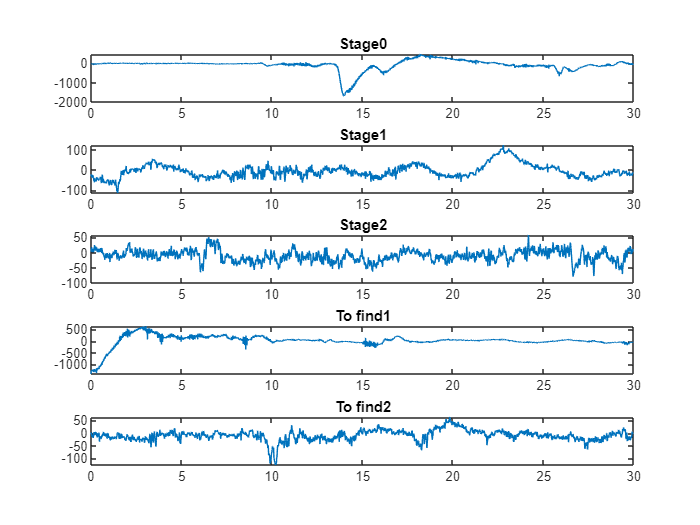

clc;clear;close all

load('matlab.mat','stage0');
X0 = transpose(stage0.Data(:,1));
load('matlab.mat','stage1');
X1 = transpose(stage1.Data(:,1));
load('matlab.mat','stage2');
X2 = transpose(stage2.Data(:,1));
X2=[X2 X2(5988)];
load('matlab.mat','to_find');
Find1 = transpose(to_find.Data(:,1));
load('matlab.mat','to_find2');
Find2 = transpose(to_find2.Data(:,1));

X0f=fftshift(fft(X0));
X1f=fftshift(fft(X1));
X2f=fftshift(fft(X2));
Find1f=fftshift(fft(Find1));
Find2f=fftshift(fft(Find2));

fs=200;
t=length(X0)/fs;
tp=0:1/fs:t-1/fs;
f=-fs/2:fs/length(X0):fs/2-fs/length(X0);

figure
subplot(5,1,1);
plot(tp,X0);
title('Stage0');

subplot(5,1,2);
plot(tp,X1);
title('Stage1');

subplot(5,1,3);
plot(tp,X2);
title('Stage2');

subplot(5,1,4);
plot(tp,Find1);
title('To find1');

subplot(5,1,5);
plot(tp,Find2);
title('To find2');

.با توجه به تابع  فیلترهای نوشته شده در قسمت قبل، سیگنال ها در باندهای فرکانسی داده شده جدا میکنیم

:نتایج به شرح زیر است 

Gama signals

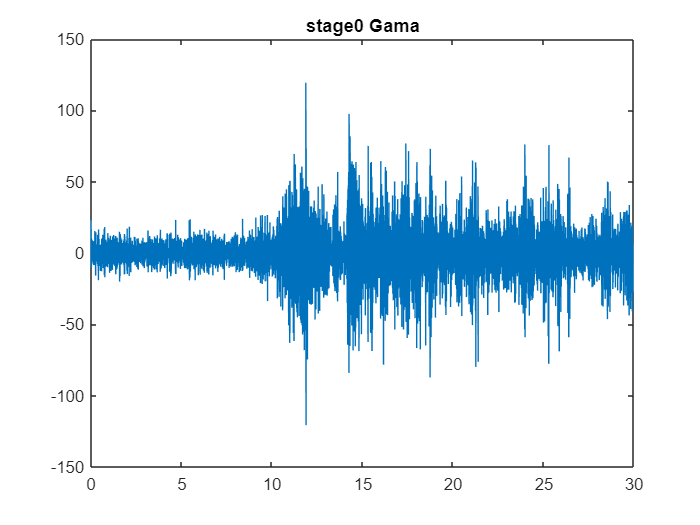

GamaX0=Gama(X0f,f,tp);
title('stage0 Gama')

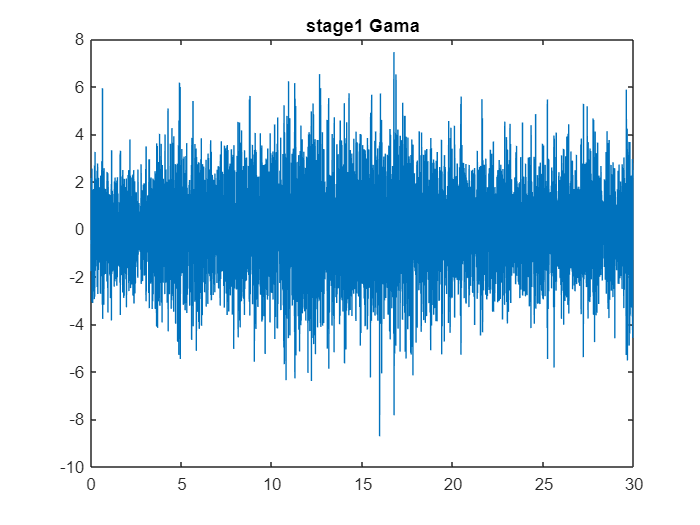

GamaX1=Gama(X1f,f,tp);
title('stage1 Gama')

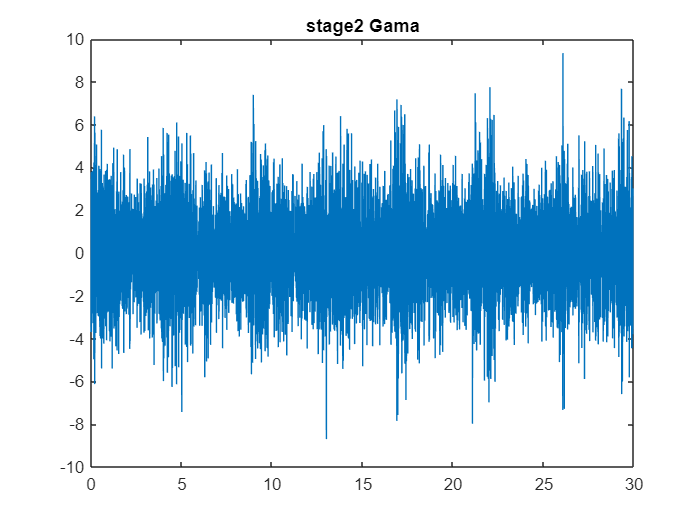

GamaX2=Gama(X2f,f,tp);
title('stage2 Gama')

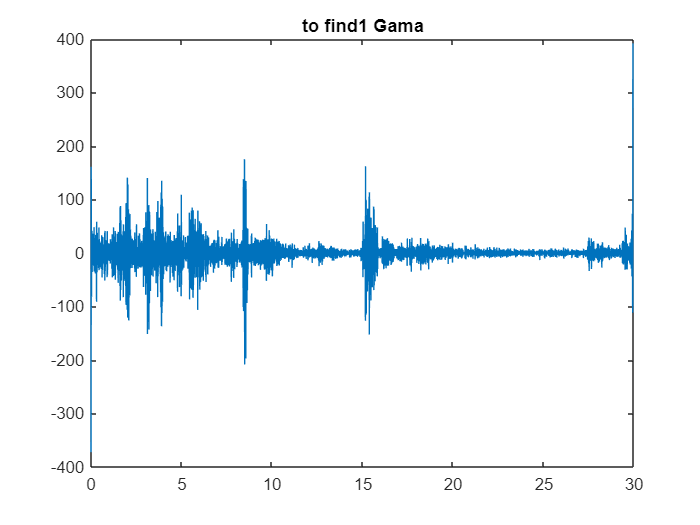

GamaFind1=Gama(Find1f,f,tp);
title('to find1 Gama')

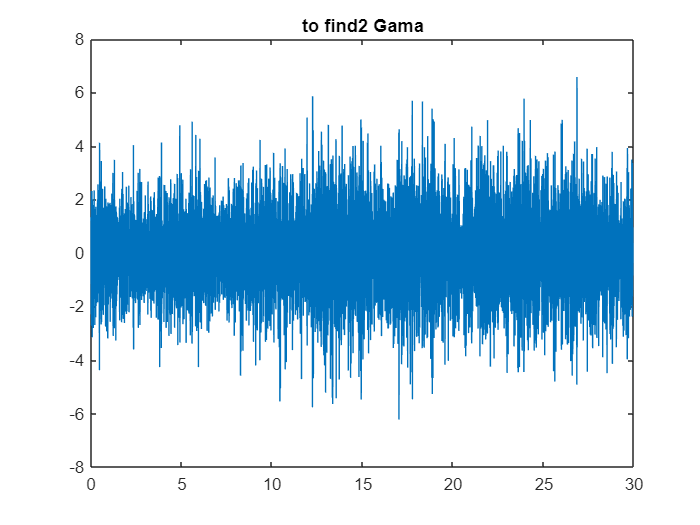

GamaFind2=Gama(Find2f,f,tp);
title('to find2 Gama')

Beta signals

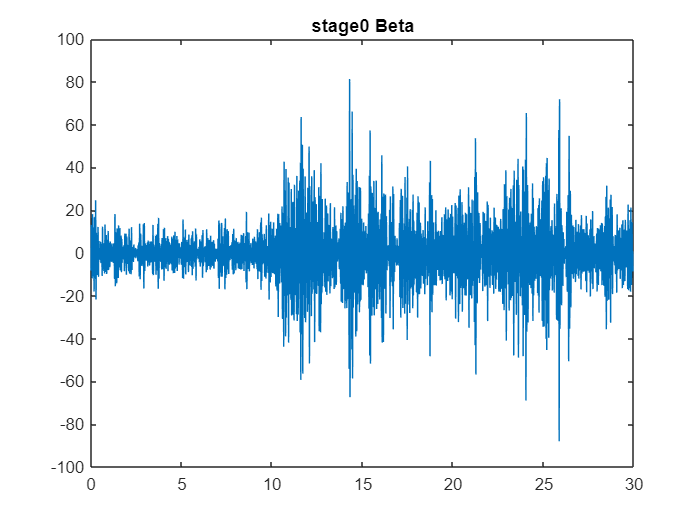

BetaX0=Beta(X0f,f,tp);
title('stage0 Beta')

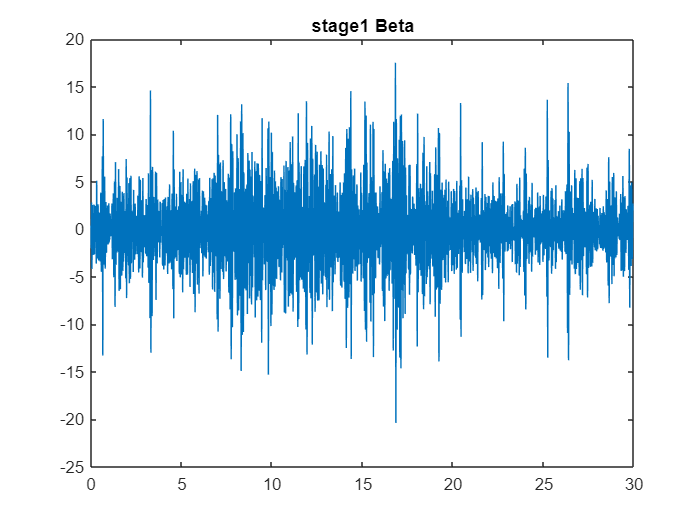

BetaX1=Beta(X1f,f,tp);
title('stage1 Beta')

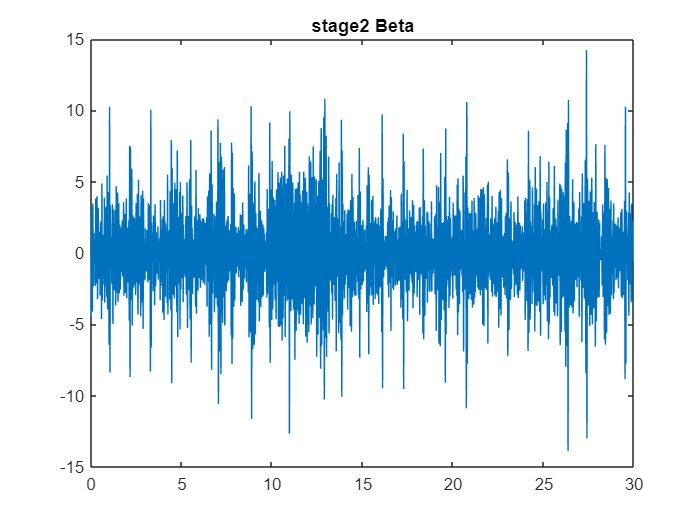

BetaX2=Beta(X2f,f,tp);
title('stage2 Beta')

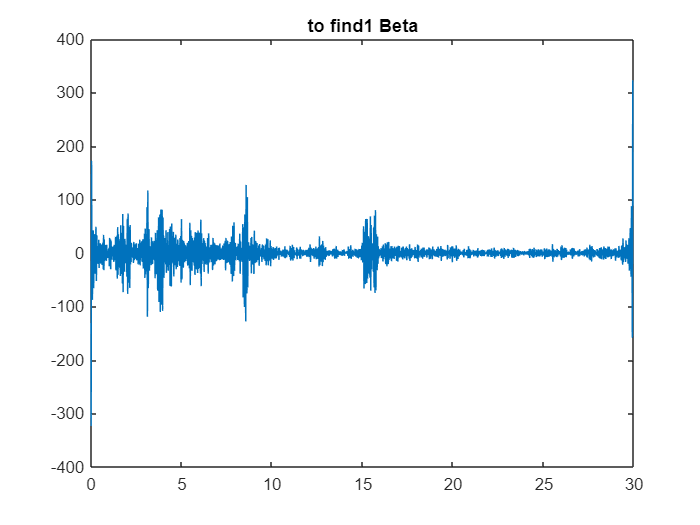

BetaFind1=Beta(Find1f,f,tp);
title('to find1 Beta')

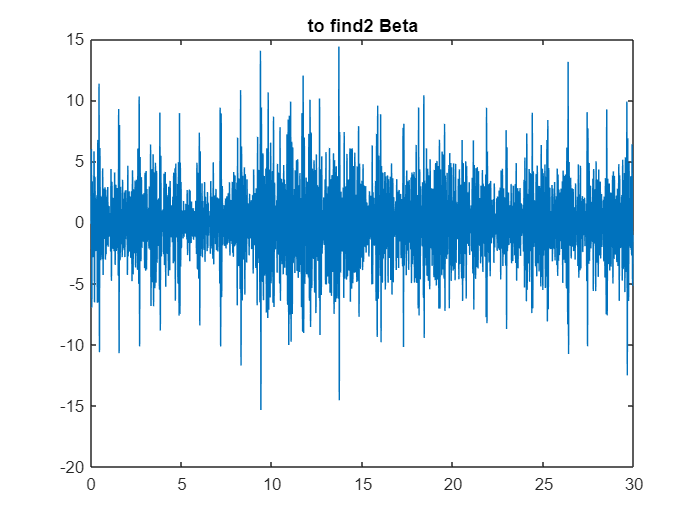

BetaFind2=Beta(Find2f,f,tp);
title('to find2 Beta')

Alpha signals

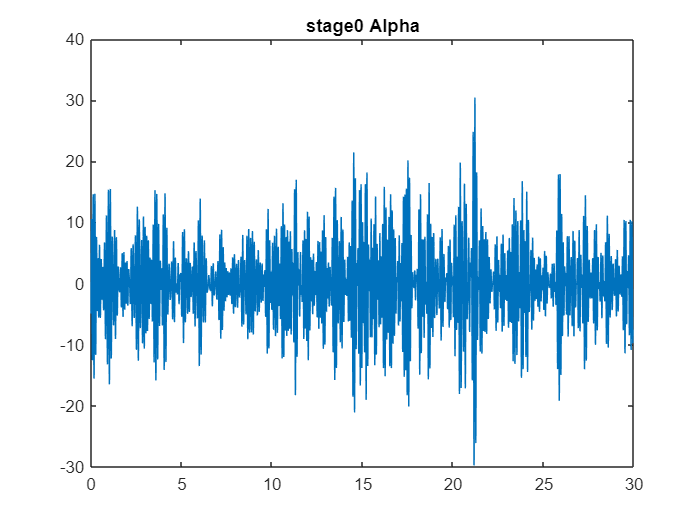

AlphaX0=Alpha(X0f,f,tp);
title('stage0 Alpha')

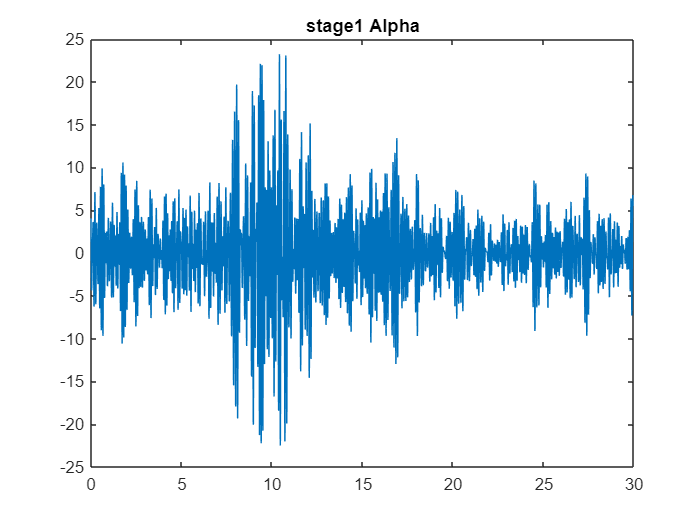

AlphaX1=Alpha(X1f,f,tp);
title('stage1 Alpha')

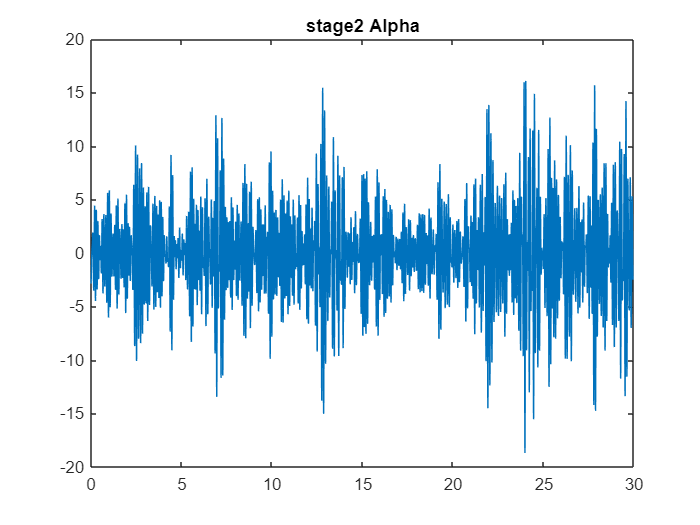

AlphaX2=Alpha(X2f,f,tp);
title('stage2 Alpha')

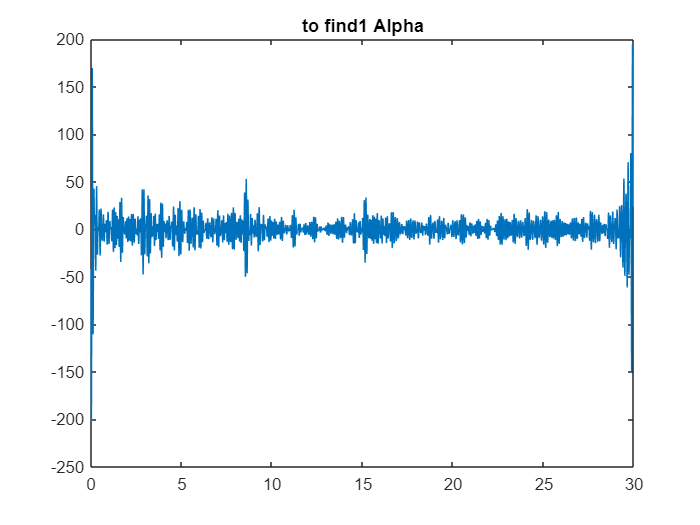

AlphaFind1=Alpha(Find1f,f,tp);
title('to find1 Alpha')

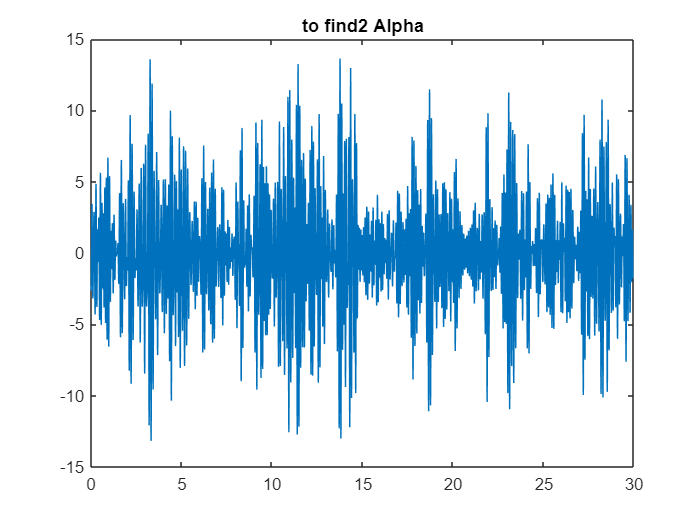

AlphaFind2=Alpha(Find2f,f,tp);
title('to find2 Alpha')

Tetha signals

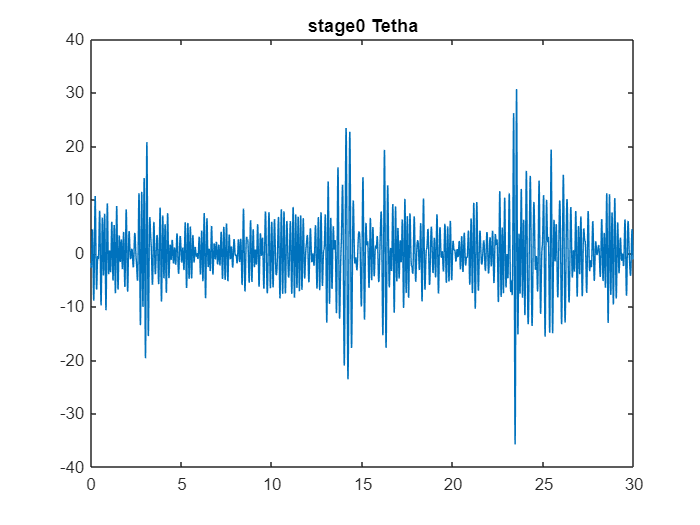

TethaX0=Tetha(X0f,f,tp);
title('stage0 Tetha')

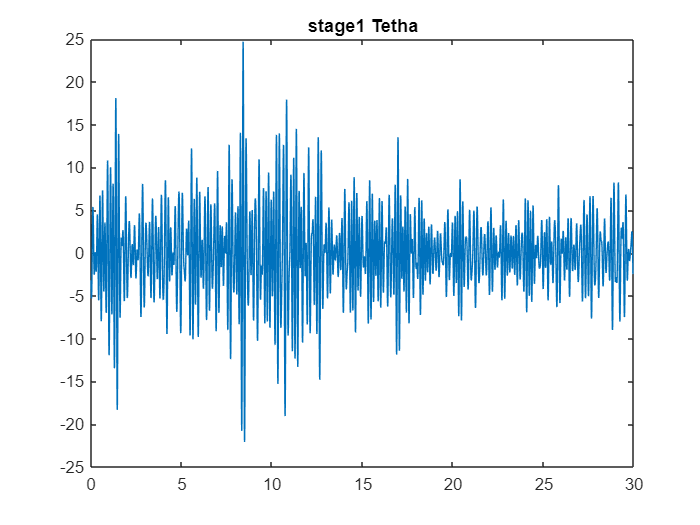

TethaX1=Tetha(X1f,f,tp);
title('stage1 Tetha')

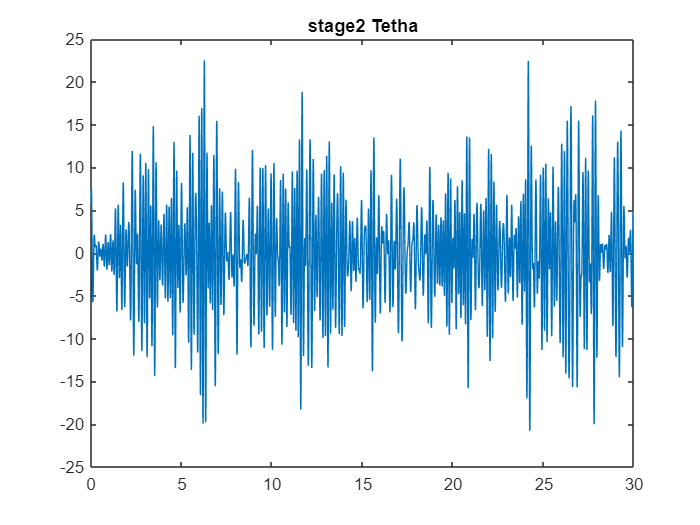

TethaX2=Tetha(X2f,f,tp);
title('stage2 Tetha')

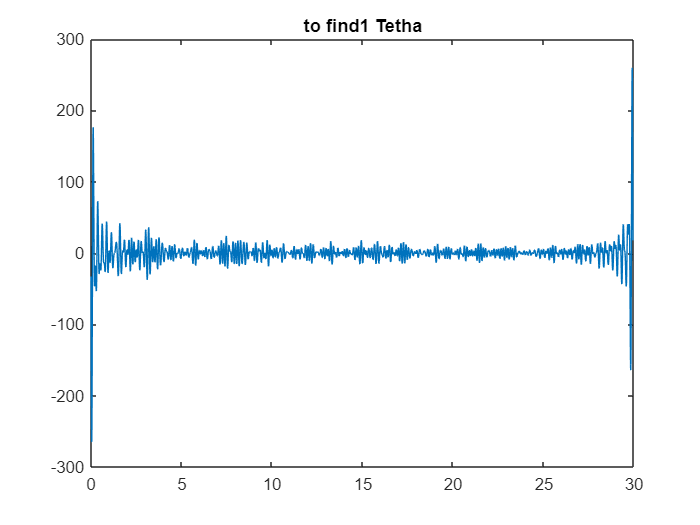

TethaFind1=Tetha(Find1f,f,tp);
title('to find1 Tetha')

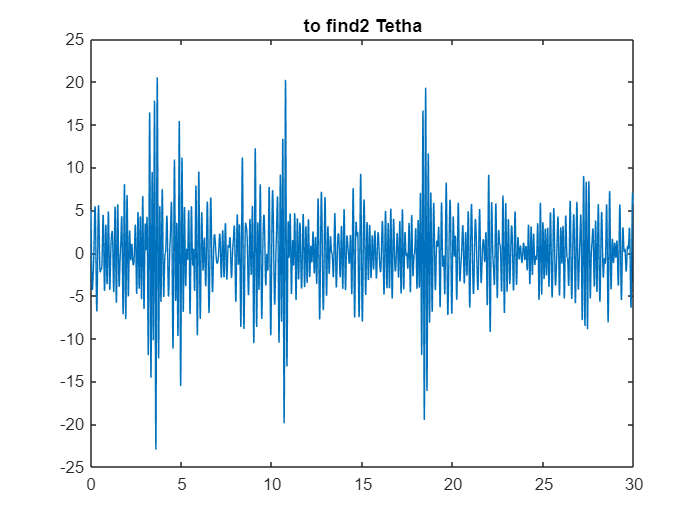

TethaFind2=Tetha(Find2f,f,tp);
title('to find2 Tetha')

Delta signals

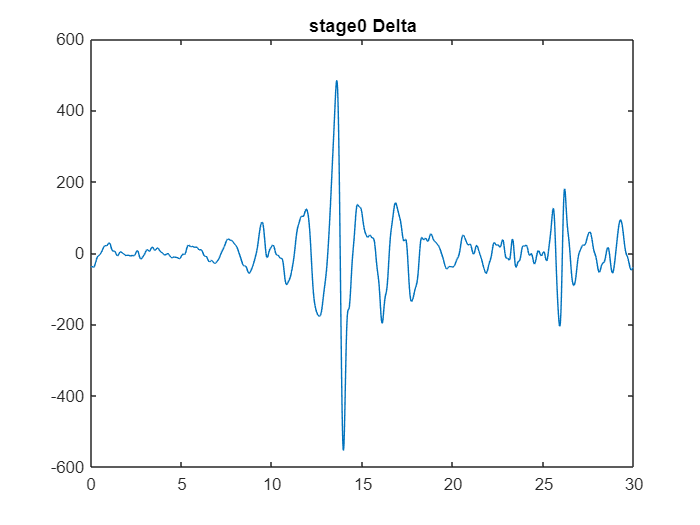

DeltaX0=Delta(X0f,f,tp);
title('stage0 Delta')

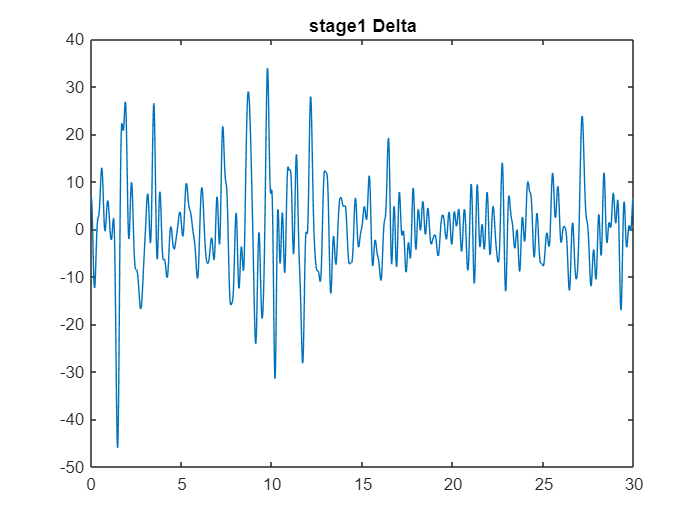

DeltaX1=Delta(X1f,f,tp);
title('stage1 Delta')

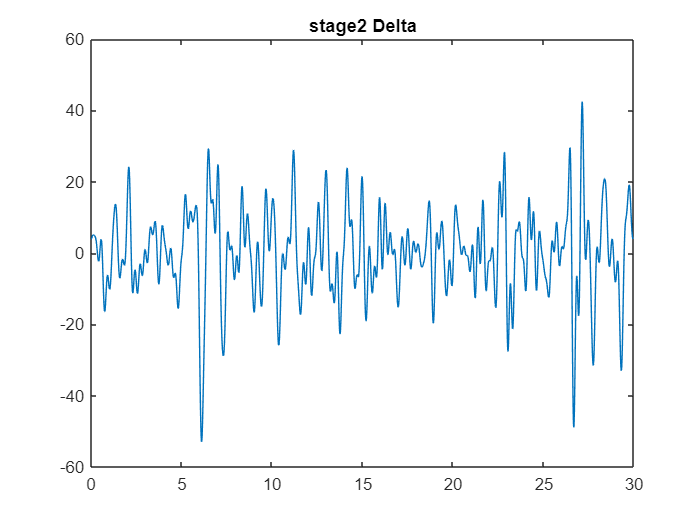

DeltaX2=Delta(X2f,f,tp);
title('stage2 Delta')

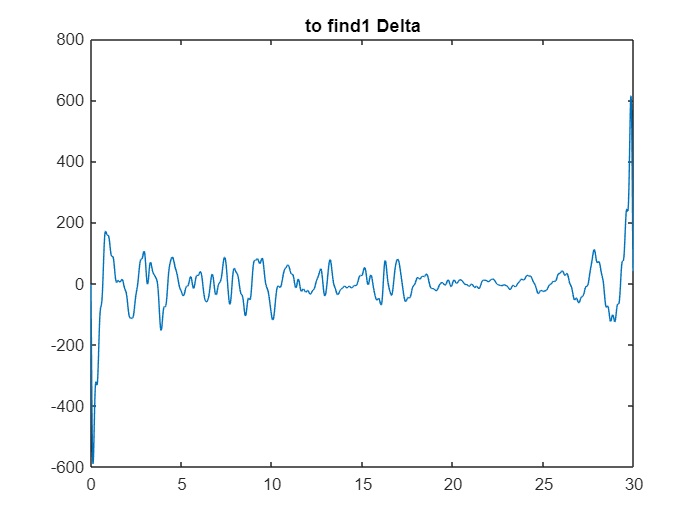

DeltaFind1=Delta(Find1f,f,tp);
title('to find1 Delta')

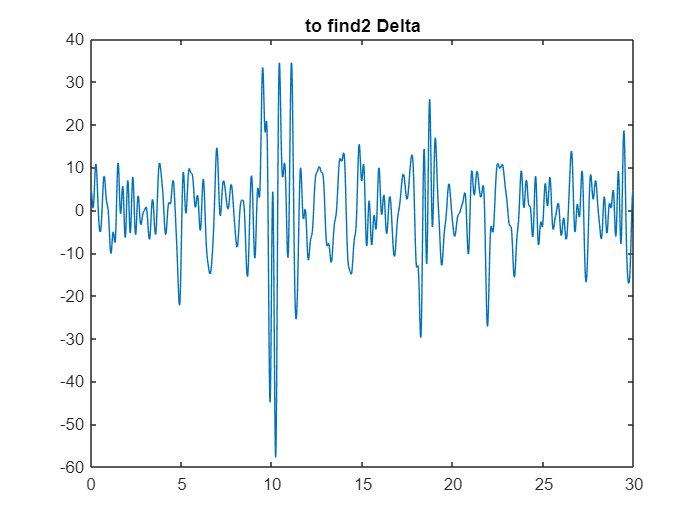

DeltaFind2=Delta(Find2f,f,tp);
title('to find2 Delta')

.سپس درصد خطای آن ها را محاسبه میکنیم. باید دقت شود که باید فرکانس ها را جدا جدا مقایسه کنیم

Error for signals 

Gamaerr10=immse(normalize(GamaFind1),normalize(GamaX0));
Gamaerr11=immse(normalize(GamaFind1),normalize(GamaX1));
Gamaerr12=immse(normalize(GamaFind1),normalize(GamaX2));
Gamaerr20=immse(GamaFind2,GamaX0);
Gamaerr21=immse(GamaFind2,GamaX1);
Gamaerr22=immse(GamaFind2,GamaX2);

Betaerr10=immse(normalize(BetaFind1),normalize(BetaX0));
Betaerr11=immse(normalize(BetaFind1),normalize(BetaX1));
Betaerr12=immse(normalize(BetaFind1),normalize(BetaX2));
Betaerr20=immse(BetaFind2,BetaX0);
Betaerr21=immse(BetaFind2,BetaX1);
Betaerr22=immse(BetaFind2,BetaX2);

Alphaerr10=immse(normalize(AlphaFind1),normalize(AlphaX0));
Alphaerr11=immse(normalize(AlphaFind1),normalize(AlphaX1));
Alphaerr12=immse(normalize(AlphaFind1),normalize(AlphaX2));
Alphaerr20=immse(AlphaFind2,AlphaX0);
Alphaerr21=immse(AlphaFind2,AlphaX1);
Alphaerr22=immse(AlphaFind2,AlphaX2);

Tethaerr10=immse(normalize(TethaFind1),normalize(TethaX0));
Tethaerr11=immse(normalize(TethaFind1),normalize(TethaX1));
Tethaerr12=immse(normalize(TethaFind1),normalize(TethaX2));
Tethaerr20=immse(TethaFind2,TethaX0);
Tethaerr21=immse(TethaFind2,TethaX1);
Tethaerr22=immse(TethaFind2,TethaX2);

Deltaerr10=immse(normalize(DeltaFind1),normalize(DeltaX0));
Deltaerr11=immse(normalize(DeltaFind1),normalize(DeltaX1));
Deltaerr12=immse(normalize(DeltaFind1),normalize(DeltaX2));
Deltaerr20=immse(DeltaFind2,DeltaX0);
Deltaerr21=immse(DeltaFind2,DeltaX1);
Deltaerr22=immse(DeltaFind2,DeltaX2);

mean10=mean([Deltaerr10,Alphaerr10,Gamaerr10,Tethaerr10,Betaerr10]);
mean11=mean([Deltaerr11,Alphaerr11,Gamaerr11,Tethaerr11,Betaerr11]);
mean12=mean([Deltaerr12,Alphaerr12,Gamaerr12,Tethaerr12,Betaerr12]);

mean20=mean([Deltaerr20,Alphaerr20,Gamaerr20,Tethaerr20,Betaerr20]);
mean21=mean([Deltaerr21,Alphaerr21,Gamaerr21,Tethaerr21,Betaerr21]);
mean22=mean([Deltaerr22,Alphaerr22,Gamaerr22,Tethaerr22,Betaerr22]);

#### نتیجه

:با توجه به میانگین به دست آمده از میانگین خطاها، میتوان گفت که

To find 1 is related to stage1.

To find 2 is related to stage1.

مشکلی که وجود دارد این است که خطای استیج یک و تو فایند با اینکه کمتر است اما مرتبه بزرگی دارد که از نرمالیزه کردن آن استفاده کردم اما جواب فرقی نکرد 

Gama filtering

function GamaEEGt=Gama(Xf,f,t)
f1=stepfun(f,-80);
f2=stepfun(f,-30);
f3=stepfun(f,30);
filter=f1-f2+f3;
figure
GamaEEGf=Xf.*filter;
GamaEEGt=ifft(ifftshift(GamaEEGf));
plot(t,real(GamaEEGt));
end

Beta filtering

function BetaEEGt=Beta(Xf,f,t)
f1=stepfun(f,-30);
f2=stepfun(f,-13);
f3=stepfun(f,13);
f4=stepfun(f,30);
filter=f1-f2+f3-f4;

figure
BetaEEGf=Xf.*filter;
BetaEEGt=ifft(ifftshift(BetaEEGf));
plot(t,real(BetaEEGt));
end

Alpha filtering

function AlphaEEGt=Alpha(Xf,f,t)
f1=stepfun(f,-13);
f2=stepfun(f,-8);
f3=stepfun(f,8);
f4=stepfun(f,13);
filter=f1-f2+f3-f4;
figure

AlphaEEGf=Xf.*filter;
AlphaEEGt=ifft(ifftshift(AlphaEEGf));
plot(t,real(AlphaEEGt))
end

Tetha filtering

function TethaEEGt=Tetha(Xf,f,t)
f1=stepfun(f,-8);
f2=stepfun(f,-4);
f3=stepfun(f,4);
f4=stepfun(f,8);
filter=f1-f2+f3-f4;
figure

TethaEEGf=Xf.*filter;
TethaEEGt=ifft(ifftshift(TethaEEGf));
plot(t,real(TethaEEGt))
end

Delta filtering

function DeltaEEGt=Delta(Xf,f,t)
f1=stepfun(f,-4);
f2=stepfun(f,-0.5);
f3=stepfun(f,0.5);
f4=stepfun(f,4);
filter=f1-f2+f3-f4;
figure

DeltaEEGf=Xf.*filter;
DeltaEEGt=ifft(ifftshift(DeltaEEGf));
plot(t,real(DeltaEEGt))
end